# **Численные методы в СПб АУ РАН - Часть 2**

## **Задание по практике №3**

Кузьмичев Артём, 4 курс

## **№8 (алгоритмы и программы к разделу 9.2)**

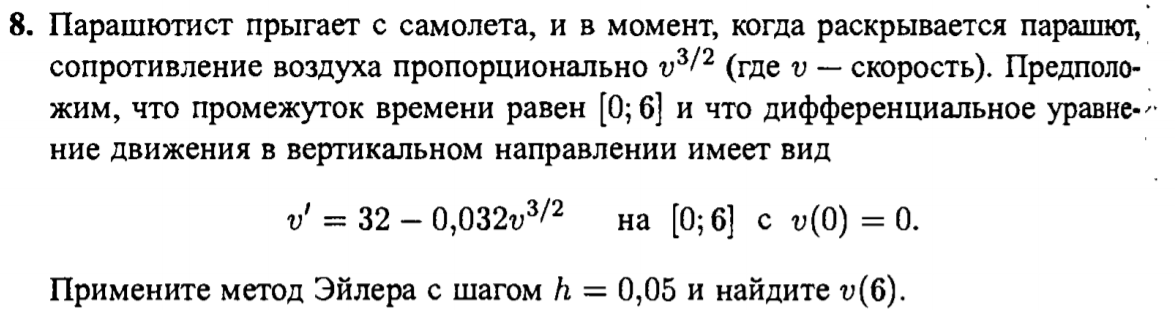

Решим задачу с помощью метода Эйлера:

acceleration = @(t,v)32 - 0.032*v^(3/2);
a = 0;
b = 6;
h = 0.05;
ya = 0;

E = euler(acceleration,a,b,ya,h);

fprintf('Скорость парашютиста к моменту t = %g составит %f м/с', b, E(end,2));

Скорость парашютиста к моменту t = 6 составит 92.497909 м/с

А также аналитически:

syms v(t) t
eqn = diff(v,t) == 32 - 0.032*v^(3/2);
cond = v(0) == 0;
vSol(t) = dsolve(eqn,cond)

 
vSol(t) =
 
[ empty sym ]
 


*Не решается...*

При желании, можно получить решение через специальные функции, из которого явным образом получить v(t) также невозможно:

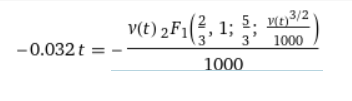

Построим график решения методом Эйлера:

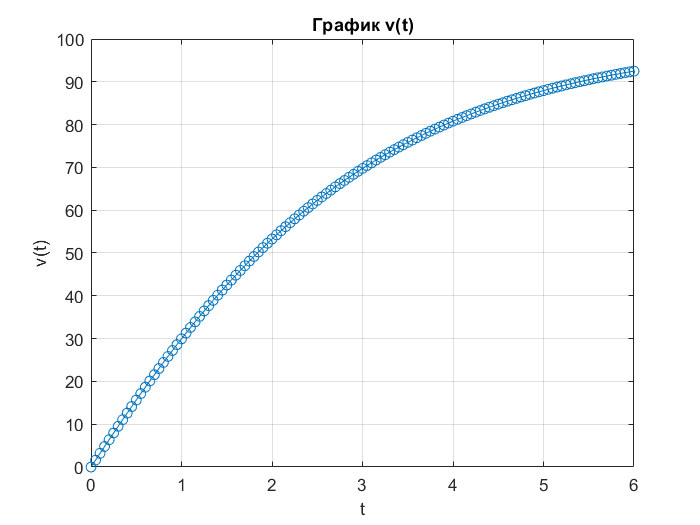

plot(E(:,1),E(:,2),'-o')
grid on
title("График v(t)");
xlabel("t")
ylabel("v(t)")

Видно, что в конечный для задачи момент времени парашютист всё ещё ускоряется.

 В случае более длительного периода наблюдения скорость выйдет на её предельное значение $v=100\;\frac{м}{с}$:

rtime = 30;

Ertime = euler(acceleration,a,rtime,ya,h);
fprintf('Скорость парашютиста к моменту t = %g составит %f м/с', rtime, Ertime(end,2));

Скорость парашютиста к моменту t = 30 составит 99.999934 м/с

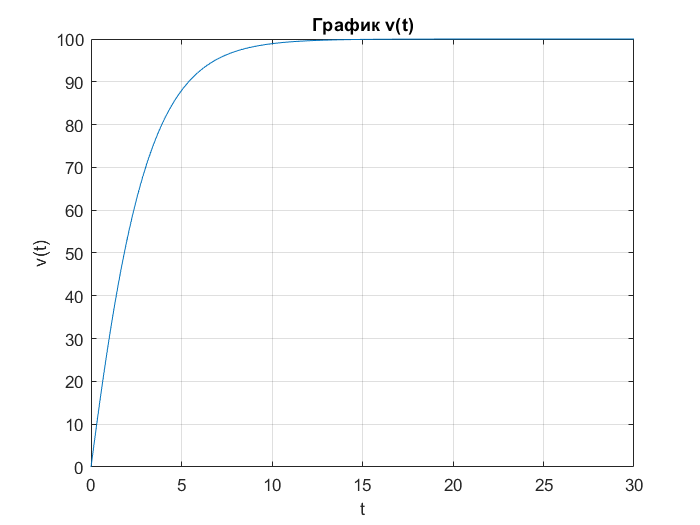

plot(Ertime(:,1),Ertime(:,2))
grid on
title("График v(t)");
xlabel("t")
ylabel("v(t)")

А что если изменить величину шага?

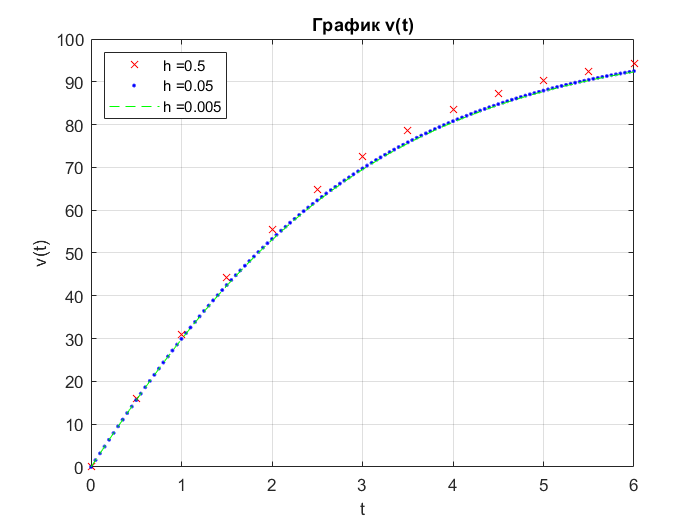

hshort = 0.005;
hlong = 0.5;
Ehshort = euler(acceleration,a,b,ya,hshort);
Ehlong = euler(acceleration,a,b,ya,hlong);


plot(Ehlong(:,1),Ehlong(:,2),'rx')
grid on
title("График v(t)");
xlabel("t")
ylabel("v(t)")

hold on

plot(E(:,1),E(:,2), 'b.');
plot(Ehshort(:,1),Ehshort(:,2),"g--");
legend("h =0.5", "h =0.05", "h =0.005",'Location','northwest')

fprintf('Вычисленная при значении величины шага h = %g скорость парашютиста к моменту t = %g составит %f м/с', hlong, b, Ehlong(end,2));

Вычисленная при значении величины шага h = 0.5 скорость парашютиста к моменту t = 6 составит 94.281778 м/с

fprintf('Вычисленная при значении величины шага h = %g скорость парашютиста к моменту t = %g составит %f м/с', h, b, E(end,2));

Вычисленная при значении величины шага h = 0.05 скорость парашютиста к моменту t = 6 составит 92.497909 м/с

fprintf('Вычисленная при значении величины шага h = %g скорость парашютиста к моменту t = %g составит %f м/с', hshort, b, Ehshort(end,2));

Вычисленная при значении величины шага h = 0.005 скорость парашютиста к моменту t = 6 составит 92.320213 м/с

## Приложение

#### Определение функции, осуществляющей алгоритмы Эйлера

function E = euler(f, a, b, ya, h)
%Вход  - f - функция
%      - a и b - крайние точки
%      - ya     - начальное условие y(a)
%      - h      - величина шага
%Выход  - E=[T',Y'] - где T' - вектор абсцисс, Y' - вектор ординат

M = round((b-a)/h); %число шагов
T = a:h:b;
Y = zeros(1, M);
Y(1)=ya;
for j=1:M
    Y(j+1) = Y(j)+h*f(T(j), Y(j));
end
E = [T' Y'];
end